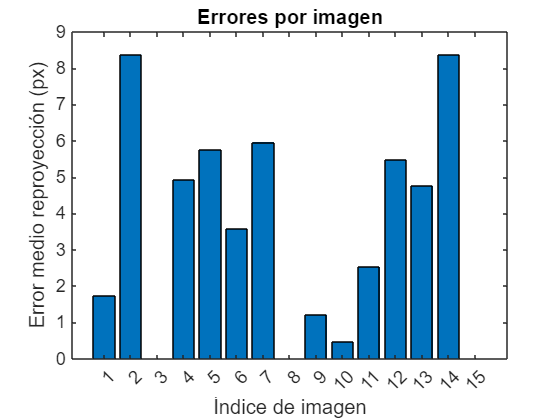

%% 1) Obtener errores de reproyección por imagen
errors = cameraParams_proyecto.ReprojectionErrors;  % 48×2×15
numImages = size(errors,3);

meanErr = zeros(numImages,1);
for i = 1:numImages
    perPoint = sqrt(sum(errors(:,:,i).^2,2)); 
    meanErr(i) = mean(perPoint);
end

%% 2) Visualizar y decidir un umbral
figure;
bar(meanErr);
xlabel('Índice de imagen');
ylabel('Error medio reproyección (px)');
title('Errores por imagen');

threshold = 1;  % px

%% 3) Filtrar las vistas buenas
goodIdx = find(meanErr <= threshold);
fprintf('Usaremos %d de %d imágenes (umbral=%.1f px)\n', numel(goodIdx), numImages, threshold);

Usaremos 1 de 15 imágenes (umbral=1.0 px)



%% 4) Recalibrar solo con las buenas
% (imagenPoints es [#corners × 2 × #images], worldPoints es [#corners×2])
params_refined = estimateCameraParameters( ...
    imagePoints(:,:,goodIdx), worldPoints, ...
    'ImageSize', ImageSize, ...
    'EstimateTangentialDistortion', true, ...
    'NumRadialDistortionCoefficients', 2);

Unrecognized function or variable 'ImageSize'.


%% 5) Comprobar nueva calidad
fprintf('Nuevo MeanReprojectionError = %.3f px\n', params_refined.MeanReprojectionError);
figure; showReprojectionErrors(params_refined);
title('Errores refinados tras filtrar vistas malas');